clc; clear; close all;

%% --- Load dataset ---
opts = detectImportOptions('games.csv');
moveVars = {'MOVE1','MOVE2','MOVE3','MOVE4','MOVE5','MOVE6','MOVE7'};
for v = moveVars
    opts = setvaropts(opts, v{1}, 'Type', 'string');
end
data = readtable('games.csv', opts);

inputs = [];
scores = [];

% Map game results to scores: win=0, draw=5, loss=10
classToScore = containers.Map({'win','loss','draw'}, [0, 10, 5]);

for row = 1:height(data)
    result = lower(data.CLASS{row});
    if ~isKey(classToScore, result)
        continue; % skip unknown classes
    end
    finalScore = classToScore(result);
    
    % Extract moves and convert '?' to NaN
    movesStr = data{row, moveVars};
    moves = nan(1, length(movesStr));
    for i = 1:length(movesStr)
        if movesStr{i} ~= "?" && movesStr{i} ~= ""
            moves(i) = str2double(movesStr{i});
        end
    end
    lastMoveIdx = find(~isnan(moves), 1, 'last');
    if isempty(lastMoveIdx)
        continue
    end
    moves = moves(1:lastMoveIdx);
    
    % For each move, build the board state before that move,
    % assign final game score as target (regression)
    for moveIdx = 1:lastMoveIdx
        board = zeros(1,9);
        for m = 1:moveIdx-1
            pos = moves(m) + 1; % convert 0-based to 1-based indexing
            if mod(m,2) == 1
                board(pos) = 1;   % Player 1 marker
            else
                board(pos) = -1;  % Player 2 marker
            end
        end
        
        % Encode board as 3x3x3 one-hot tensor
        tensorSample = zeros(3,3,3);
        for c = 1:9
            rowi = ceil(c/3);
            coli = mod(c-1,3) + 1;
            if board(c) == 1
                tensorSample(rowi, coli, 1) = 1; % Player 1
            elseif board(c) == -1
                tensorSample(rowi, coli, 2) = 1; % Player 2
            else
                tensorSample(rowi, coli, 3) = 1; % Empty
            end
        end
        
        inputs = cat(4, inputs, tensorSample);
        scores = [scores; finalScore];
    end
end

fprintf('Total samples extracted: %d\n', size(inputs, 4));

Total samples extracted: 9343


Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |         0.68 |         1.16 |       0.2335 |       0.6781 |          0.0010 |
|       1 |          30 |       00:00:01 |         0.48 |         0.40 |       0.1133 |       0.0789 |          0.0010 |
|       1 |          50 |       00:00:02 |         0.35 |              |       0.0601 |              |          0.0010 |
|       1 |          60 |       00:00:02 |         0.37 |         0.36 |       0.0703 |       0.0663 |          0.0010 |
|       

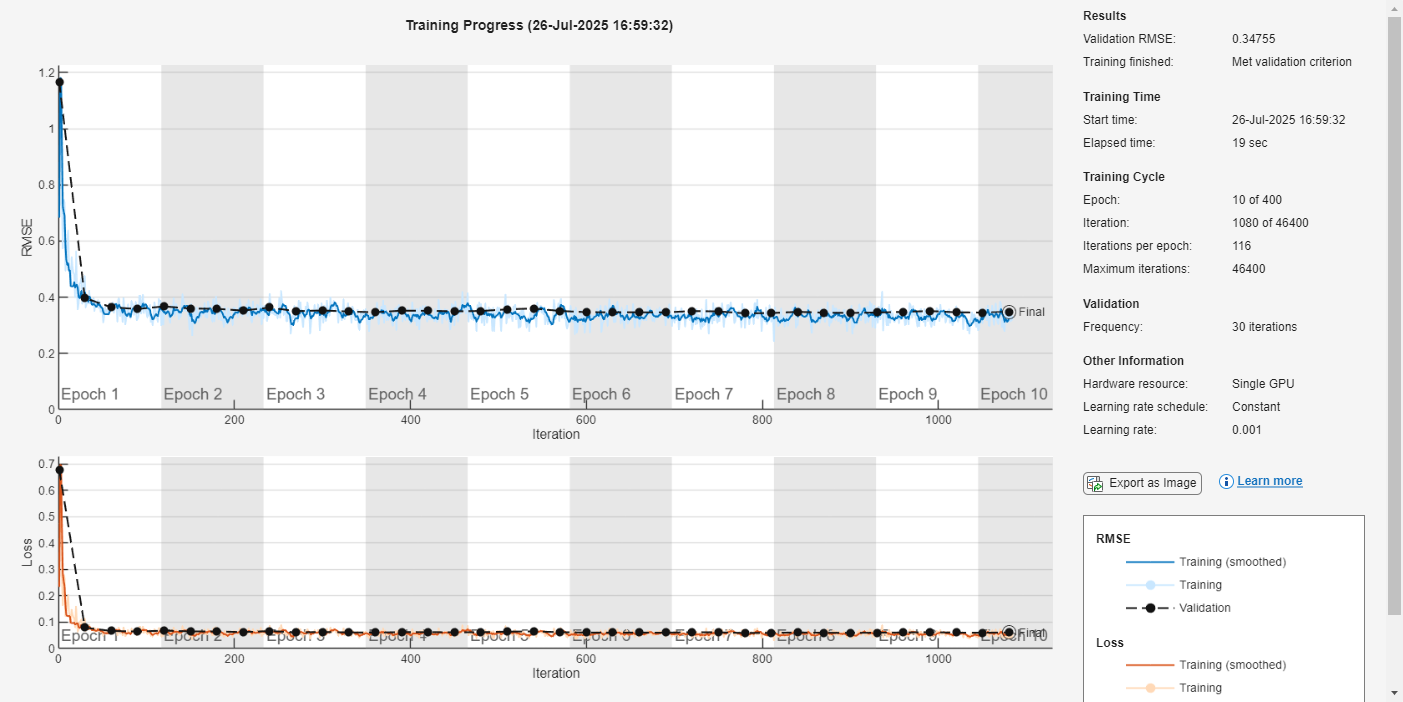


%% --- Prepare training and test sets ---

% Scale targets to [0,1] for regression
targetsScaled = scores / 10;

cv = cvpartition(length(targetsScaled), 'HoldOut', 0.2);
trainIdx = training(cv);
testIdx = test(cv);

XTrain = inputs(:,:,:,trainIdx);
YTrain = targetsScaled(trainIdx);

XTest = inputs(:,:,:,testIdx);
YTest = targetsScaled(testIdx);

%% --- Define CNN regression network ---

layers = [
    imageInputLayer([3 3 3], 'Normalization', 'none', 'Name', 'input')
    
    convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv1')
    batchNormalizationLayer('Name', 'bn1')
    reluLayer('Name', 'relu1')
    
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv2')
    batchNormalizationLayer('Name', 'bn2')
    reluLayer('Name', 'relu2')
    
    fullyConnectedLayer(128, 'Name', 'fc1')
    reluLayer('Name', 'relu3')
    
    fullyConnectedLayer(1, 'Name', 'fc_out')
    regressionLayer('Name', 'regression_output')
];

%% --- Training options ---

options = trainingOptions('adam', ...
    'MaxEpochs', 400, ...
    'InitialLearnRate', 1e-3, ...
    'MiniBatchSize', 64, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', true, ...
    'ValidationData', {XTest, YTest}, ...
    'ValidationFrequency', 30, ...
    'ValidationPatience', 10);

%% --- Train the network ---

net = trainNetwork(XTrain, YTrain, layers, options);


%% --- Evaluate on test set ---

YPredScaled = predict(net, XTest);
YPred = YPredScaled * 10;       % scale back to [0,10]
YTrue = YTest * 10;

rmse = sqrt(mean((YPred - YTrue).^2));
fprintf('Test RMSE: %.3f\n', rmse);

Test RMSE: 3.476



%% --- Example usage: predict score for a new board ---

% Suppose newBoardTensor is a 3x3x3 tensor representing the board state:
% predictedScore = predict(net, newBoardTensor);
% predictedScore = predictedScore * 10;
% fprintf('Predicted score (0-10): %.3f\n', predictedScore);
